# Cosmology Calculations

Lauri Jokinen, 2023.

This document is used together with file `runge_kutta.m` for plotting figures. The script is made with Matlab version 2021b, with Live Script enabled. The code is much more readable with Live Script swiched on.

The script has a function for each plot, and the functions are called in section 'Calling the plotting Functions'. This way toggling the plots on/off is easy.

The functions have many similar commands, so some of the code further down is not commented as well as the code above it.

close all    % Close all open figures
format long  % With this Matlab won't round results in console

## Calculation Parameters and Global Variables

Here we declare "global" variables in struct G. This struct is passed to nearly all functions.

First is Hubble constant. With the correction factor, the constant is in unit (Gyr)^-1.

G.save = true;
G.correction = 3.15576 / (1.495978707 * 6.48 / pi) / 10;
G.H = 0.6726 * G.correction;

Precision value: smaller gives more precise result. This single value affects the precision of various algorithms. 

G.precision = 1e-10; % 1e-12 on aika jees

Set options for Matlab's equation system solver `fsolve` and optimizer `fminunc`.

G.fsolveOptions  = optimoptions('fsolve', ...
            'OptimalityTolerance',G.precision, ...
            'FunctionTolerance', G.precision, ...
            'StepTolerance',G.precision, ...
            'MaxFunctionEvaluations', ceil(sqrt(1/G.precision)), ...
            'MaxIterations', ceil(sqrt(1/G.precision)), ...
            'Display', 'off');

G.fminuncOptions = optimoptions('fminunc', ...
            'OptimalityTolerance', G.precision, ...
            'StepTolerance', G.precision, ...
            'MaxFunctionEvaluations', ceil(sqrt(1/G.precision)), ...
            'MaxIterations', ceil(sqrt(1/G.precision)), ...
            'Display', 'off');

Maximum t-value for differential equation solver, in unit Gyr and starting from the big bang. In some cases it is wanted that the solver is terminated after point $a(T) = 1$ is reached. This is the limit, if we don't want to stop the solver at this point. 80 Gyr should be sufficient.

G.t_end = 80;

General parameters for the models. 

G.omegaB    = 0.049;
G.FH_omegaD = 0.268; G.FH_omegaL = 0.683;
G.F_omegaD  = 0.151; G.F_omegaL  = 0.8;

$\Omega^{\Lambda}$ for the $\Lambda \text{R}$-model is solved from equation $\Omega^{B} + \Omega^{\Lambda} + \Omega^{\Lambda R}_T = 1$. Function `flatness_solve_omegaL` is defined further down.

LR_model_cahced = memoize(@LR_model);
LR_model_cahced.CacheSize = 100;
%G.LR_omegaL = flatness_solve_omegaL(G, G.omegaB, 1, LR_model_cahced);

Record the age of the universe, using the benchmark Friedmann-model.

%[~, tH] = F_model(G, G.omegaB + G.FH_omegaD, G.FH_omegaL, true, LR_model_cahced);
%G.benchmarkAge = -tH(1);

Parameters at which $\Omega^{\Lambda \text{R}}_T$ is maximised.

%[G.omegaLR_opt, G.omegaB_opt, G.omegaL_opt] = solve_optimum(G, LR_model_cahced);

Parameter at which the $\Lambda \text{R}$-model returns the correct age of the universe, and satistfies $\Omega^D + \alpha \Omega^{\Lambda R}_T = \frac{\Omega^{\Lambda R}_{T,opt}}{\Omega^B_{opt}} \Omega^B$.

%[G.omegaD_opt, G.alpha_opt] = optimizeDalpha(G);

Some plot related variables.

% Colors
G.blue = [ 50, 110, 230]/255; G.red  = [250,  42,  30]/255;

% Line width in plots
G.lineWidth = 1;
G.legendMarkers = true; % this is put to false occationally

## Calling the Plotting Functions

Here you can select which Figures you want to plot. Comment out the ones that you don't want to plot.

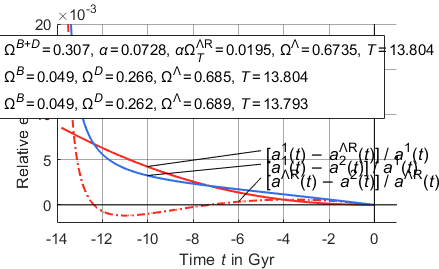

% Tests the precision of the differential equation

%[a_res, t_res, ~, y_res] = LR_model(G, 1, 0); % a0 = 1e-12 => e = 1e-10.
%disp(-t_res(1) - 2/(3*G.H));

%G.H = 1;
%B = 0;
%res = zeros(4,length(B));
%precs = linspace(1e-10^(1/2), 1e-10^(1/2), 1).^(2);
%L = sqrt(0.7426);
%figure; hold on;

%for p = 1:length(precs)
    %G.precision = precs(p);
    %[a_res_o, t_res_o, ~, y_res] =  LR_model(G, B, 0.7426);
    %[a_res, t_res, ~, y_res] = LR_model(G, B+0.000001, 0.7426); % a0 = 1e-12 => e = 1e-10.
    %[a_res_r, t_res_r] = LR_model_runge(G, B, 0.7426); % a0 = 1e-12 => e = 1e-10.
    %[a_res_l, t_res_l] =  LR_model_lapa(G, B+0.000001, 0.7426);
    %res(:,p) = [t_res(1), t_res_r(1), t_res_l(1), t_res_o(1)];
    %plot(precs(p), sqrt(0.7426) * y_res(end,2), 'o')
%end
%plot(precs, res)
%sqrt(0.7426) * y_res(end,2) + 0.7426
%legend('uusi simppeli','alkp. runge', 'lapa monimutkainen','Matlab orig.')

%[pts,y] = differenceGraphs(300, t_res, a_res, t_res_r, a_res_r, 'rel');
%plot(pts,y)

% Figure 1
%final_plot_1(G)

% Figure 2
%final_plot_50(G)

% Figure 3
%final_plot_3(G)

% Figure 4
%final_plot_4(G)

% Figure 5
%final_plot_many_B(G, LR_model_cahced)

% Figure 6 & 7 along with Tables 1-2
% FIG 7 is broken somehow!
%[omegaB_array, omegaLR, omegaL, T, omegaLR_lin, omegaL_lin] = final_plot_RB(G, LR_model_cahced);
%print_table_two_col([omegaB_array,omegaLR,omegaL,T])
%print_table_two_col([omegaB_array, omegaLR_lin, omegaL_lin])
%disp('Tarkemmat')
%print_table_two_col([omegaB_array,omegaLR,omegaL,T],9)
%print_table_two_col([omegaB_array, omegaLR_lin, omegaL_lin],9)

% Figure 8
%figure_8(G)

fig_9_to_11(G) % 10 ylimääräinen?

%%%%%%% NÄMÄ
plot_diff_H_error_age(G)

plot_diff_Ht_age(G)

## Differential Equation Solvers

The ODE system is,

$\dot{A} = H_T \sqrt{\frac{1}{At^{2}} \Omega^{B+D} +  \frac{ \alpha H_T \sqrt{\Omega^{\Lambda}}}{A^2t}  B + A^2 \Omega^{\Lambda}} - \frac{2}{3 t}A$,

$\dot{B} = \frac{1}{t} \left[ A \cdot e^{-t \cdot H_T \sqrt{\Omega^{\Lambda}}} - \frac{5}{3} B \right]$.

function [a_res, t_res, omega_LR, y_res] = LR_model(G, omegaBD, omegaL, alpha, terminate_T)
    if nargin==4
        terminate_T = true;
    elseif nargin==3
        terminate_T = true;
        alpha = 1;
    end
    
    %precision = min(G.precision, 1e-8); % the ode returns nonsense with too large precision
    precision = G.precision;
    
    %t0 = G.precision*100;
    %a0 = (3/2 * G.H * t0 * sqrt(omegaBD))^(2/3);
    %b0 = 3/5 * a0 * t0;
    
    a0 = G.precision*10000;
    t0 = a0^(3/2) / (3/2 * G.H * sqrt(omegaBD));
    b0 = 3/5 * a0 * t0;

    if omegaBD == 0
        t0 = 0;
        b0 = 0;
        a0 = 0;
    end

    y_dot = @(t,y)odes(t, y, G.H, omegaBD, omegaL, alpha);
    opts = odeset('Events',@(t,y)ode_events(t, y, y_dot, terminate_T),'RelTol',1e-1*precision,'AbsTol',1e-2*precision); % Create events function
    
    [t_res, y_res, te, ye] = ode23s(y_dot, [t0, G.t_end], [a0;b0], opts);
    

    t0 = linspace(0,t0,100);
    a0 = (3/2 * G.H * t0 * sqrt(omegaBD)).^(2/3);
    b0 = 3/5 * a0 .* t0;

    y_res = [[a0.',b0.']; y_res];
    t_res = [t0.'; t_res];

    % Add 'events' to the result vectors
    for p = 1:length(te)
        ind = sum(t_res < te(p));
        t_res = [t_res(1:ind);   te(p);   t_res((ind+1):end)];
        y_res = [y_res(1:ind,:); ye(p,:); y_res((ind+1):end,:)];
    end

    % Remove identical points
    p = 1;
    while p < length(t_res)
        if t_res(p) == t_res(p+1) || y_res(p,1) == y_res(p+1,1) || y_res(p,2) == y_res(p+1,2)
            t_res(p+1) = [];
            y_res(p+1,:) = [];
        else
            p = p+1;
        end
    end
    
    a_res = y_res(:,1);
    a_res(isinf(a_res)|isnan(a_res)) = 0;
    [~, ind_T] = min(abs(a_res - 1));
    ind_T = ind_T(1);
    t_res = t_res - t_res(ind_T);
    omega_LR = G.H * sqrt(omegaL) * y_res(:,2) ./ a_res(:,1);
end

function y_dot = odes(t, y, H, omegaBD, omegaL, alpha)
    A_dot = H * sqrt(omegaBD/y(1) + alpha*H*sqrt(omegaL)*y(2)/(y(1))^2 + (y(1))^2*omegaL);
    B_dot = y(1) * exp(-t * H * sqrt(omegaL));
    A_dot(~isfinite(A_dot)) = H * (alpha * sqrt(omegaL) / 2)^(1/3); % TODO korjaa tää, in case BD=0
    B_dot(~isfinite(B_dot)) = 0;
    y_dot = real([A_dot;B_dot]);
end

function [value,isterminal,direction] = ode_events(t, y, y_dot, terminate_T)
    y_dot_val = y_dot(t,y);
    value = [y(1) - 1; y(1)*y_dot_val(2) - y(2)*y_dot_val(1)];
    isterminal = [terminate_T; 0];
    direction = [0; 0];
end

The Friedmann model's equations are as above, but $\alpha = 0$,

function [a_res, t_res, omega_LR, AB] = F_model(G, omegaBD, omegaL, terminate_T, LR_model_cache)
    if nargin==3
        terminate_T = true;
        [a_res, t_res, omega_LR, AB] = LR_model(G, omegaBD, omegaL, 0, terminate_T);
    elseif nargin==4
        [a_res, t_res, omega_LR, AB] = LR_model(G, omegaBD, omegaL, 0, terminate_T);
    else
        [a_res, t_res, omega_LR, AB] = LR_model_cache(G, omegaBD, omegaL, 0, terminate_T);
    end
end

Simple function that returns $\Omega^{\Lambda \text{R}}_T$. This function is useful with solvers furher down.

function omegaLR_T = LR_model_omegaLR_T(G, omegaB, omegaL, alpha, LR_model_cahce)
    if nargin==3
        alpha = 1;
    end
    if nargin==5
        [~, ~, omega_LR] = LR_model_cahce(G, omegaB, omegaL, alpha);
        omegaLR_T = omega_LR(end);
        return
    end
    [~, ~, omega_LR] = LR_model(G, omegaB, omegaL, alpha);
    omegaLR_T = omega_LR(end);
end

## Other Equation Solver Functions

Solves $\Omega^{\Lambda}$ from the flatness algorithm $\Omega^B + \Omega^{\Lambda} + \alpha \Omega^{\Lambda \text{R}}_T = 1$. Evaluation of $ \Omega^{\Lambda \text{R}}_T$ requires integration.

function omegaL = flatness_solve_omegaL(G, omegaB, alpha, LR_model_cahce)
    if omegaB==1
        omegaL = 0;
        return
    end
    if nargin==2
        alpha = 1;
    end
    if nargin==4
        omegaL = fsolve(@(omegaL) alpha*LR_model_omegaLR_T(G, omegaB, abs(omegaL), alpha, LR_model_cahce) + omegaB + abs(omegaL) - 1, ...
                    (1-omegaB)^1.6,... % initial guess
                    G.fsolveOptions);
        omegaL = abs(omegaL);
        return
    end
    omegaL = fsolve(@(omegaL) alpha*LR_model_omegaLR_T(G, omegaB, abs(omegaL), alpha) + omegaB + abs(omegaL) - 1, ...
                    (1-omegaB)^1.6,... % initial guess
                    G.fsolveOptions);
    omegaL = abs(omegaL);
end

Same as above, except $a$ is approximated with $a = H_T \, t$. No integration is needed in this algorithm.

function omegaL = flatness_solve_omegaL_linear(G, omegaB)
    if omegaB == 1
        omegaL = 0;
    else
        omegaL = fsolve(@(omegaL)real(omegaB + (1-exp(-sqrt(omegaL))*(1+sqrt(omegaL)))/sqrt(omegaL) + omegaL) - 1, ...
                        0.7*(1-omegaB), ... % initial guess
                        G.fsolveOptions);
    end
end

Solves $\alpha$ from flatness equation, $\Omega^B + \Omega^{\Lambda} + \alpha \Omega^{\Lambda \text{R}}_T  + \Omega^D = 1$.

function alpha = flatness_solve_alpha(G, omegaBD, omegaL)
    alpha = fsolve(@(alpha)omegaBD + omegaL + alpha*LR_model_omegaLR_T(G, omegaBD, omegaL, alpha) - 1, ...
                    0.2, ... % initial guess
                    G.fsolveOptions);
end

Solver for optimum $\max_{\Omega^B}{\Omega^{\Lambda \text{R}}_T}$.  $\Omega^{\Lambda}$ is solved from the flatness equation, $\Omega^B + \Omega^{\Lambda} + \Omega^{\Lambda \text{R}}_T = 1$. In the function we solve $\min_{\Omega^B}{(-\Omega^{\Lambda \text{R}}_T)}$

function [omegaLR, omegaB, omegaL] = solve_optimum(G, LR_model_cache)
    if nargin == 2
        [omegaB, omegaLRneg] = fminunc(@(omegaB)-LR_model_omegaLR_T(G, omegaB, flatness_solve_omegaL(G,omegaB,1,LR_model_cache), 1, LR_model_cache), ...
                                    0.0458, ... % initial guess
                                    G.fminuncOptions);
    else
        [omegaB, omegaLRneg] = fminunc(@(omegaB)-LR_model_omegaLR_T(G, omegaB, flatness_solve_omegaL(G,omegaB)), ...
                                    0.0458, ... % initial guess
                                    G.fminuncOptions);
    end
    omegaLR = -omegaLRneg;
    omegaL = 1 - omegaB - omegaLR;
end

Solver for $\Omega^D$ and $\alpha$, such that age of the universe matches with the Friedmann model, and $\Omega^D + \alpha \Omega^{\Lambda \text{R}}_T = \frac{\Omega^{\Lambda \text{R}}_{T,opt}}{\Omega^B_{opt}} \Omega^B$.

function [omegaD_opt, alpha_opt] = optimizeDalpha(G)
    x = fsolve(@(x)targetValTime(G, x(1), x(2)),[0.26,0.083], G.fsolveOptions);
    omegaD_opt = x(1);
    alpha_opt = x(2);
end

Equations for solving optimal parameters for $\Omega^{\Lambda \text{R}}$-model. Not solvers, just equations, from which we want to solve for zero.

% function value = targetTime(G, alpha, omegaD)
%     value = targetTimeLR(G, alpha, omegaD, 0);
%     value = value(1);
% end
% 
% function value = targetVal(G, alpha, omegaD)
%     value = targetValTime(G, omegaD, alpha);
%     value = value(1);
% end

function res = targetTimeLR(G, alpha, omegaD, alphaLR)
    omegaB = G.omegaB; benchmarkAge = G.benchmarkAge;
    omegaL = flatness_solve_omegaL(G, omegaB + omegaD, alpha);
    [~, t, omegaLR] = LR_model(G, omegaB + omegaD, omegaL, alpha);
    res(1) = t(1) + benchmarkAge;
    res(2) = omegaLR(end)*alpha - alphaLR;
end

function values = targetValTime(G, omegaD, alpha)
    omegaLR_opt = G.omegaLR_opt; omegaB_opt = G.omegaB_opt; omegaB = G.omegaB; benchmarkAge = G.benchmarkAge;
    omegaL = 1 - omegaLR_opt/omegaB_opt * omegaB - omegaB;
    [~, t, omega_LR] = LR_model(G, omegaB + omegaD, omegaL, alpha);
    values(1) = (omegaD + alpha*omega_LR(end)) / omegaB - omegaLR_opt/omegaB_opt;
    values(2) = t(1) + benchmarkAge;
 end

## Tools for plotting and printing results

This section contains some general functions for plotting. Not relevant to any calculations.

Rounds number to three or four decimals in a string format.

function res = print_num2(x,T,precision)
    if nargin==1
        T=false;
        precision=0;
    elseif nargin==2
        precision=0;
    elseif nargin==3 && precision ~= 0
        res = num2str(x,precision);
        return
    end
    if T
        res = num2str(x,'%.3f');
    elseif ~min(x >= 1)
        res = num2str(round(x,4));
    else
        res = num2str(round(x,3));
    end
    % num2str(12.,'%.3E') eksponenttimuoto, mutta ilman kun 0.99995 <= x < 9999.5
end

Saves current plot to current Matlab-directory. The function adds a grid and modifies the legend. Optionally adds a box showing $H_T$.

function save_plot(G, name, leg, plot_HT) % 'leg' stands for legend
    
    figuresize(19.5, 11.96, 'cm')
    grid on
    set(gca,'GridAlpha', 0.4);
    if ~isa(leg, 'double')
        leg.ItemTokenSize = [30,18]*0.60; % default [30,18]
    end
    if ~G.legendMarkers
        leg.ItemTokenSize = [0,18]; % default [30,18]
    end
    if plot_HT
        diff = 3; % gap between legend and H_T box in points
        legPos = leg.Position;
        leg.Units = 'points';
        legPosPt = leg.Position;
        dim = [legPos(1) legPos(2) 0 0];
        str = ['{\itH}_{\itT} = ' num2str(100 * G.H / G.correction), ' kms^{-1}Mpc^{-1}'];
    end
    
    if plot_HT && leg.Location == "northwest" && leg.Visible == "on"
        vert = 'top';
        horz = 'left';
        dim(2) = (legPosPt(2) - diff) * legPos(2) / legPosPt(2);
    elseif plot_HT && leg.Location == "northwest" && leg.Visible == "off"
        vert = 'top';
        horz = 'left';
        dim = [legPos(1) legPos(2)+legPos(4) 0 0];
    elseif plot_HT && leg.Location == "northeast" && leg.Visible == "on"
        vert = 'top';
        horz = 'right';
        dim = [legPos(1)+legPos(3) legPos(2) 0 0];
        dim(2) = (legPosPt(2) - diff) * legPos(2) / legPosPt(2);
    elseif plot_HT && leg.Location == "southeast" && leg.Visible == "on"
        vert = 'bottom';
        horz = 'right';
        dim = [legPos(1)+legPos(3) legPos(2)+legPos(4) 0 0];
        dim(2) = (legPosPt(2)+legPosPt(4) + diff) * legPos(2) / legPosPt(2);
    else
        vert = 'middle';
        horz = 'center';
    end
    
    if plot_HT
        annotation('textbox',dim,'String',str,'FitBoxToText','on','FontSize',leg.FontSize,'BackgroundColor','white','Margin',3,'VerticalAlignment',vert,'HorizontalAlignment',horz,'LineWidth',leg.LineWidth);
    end
    if ~G.save
        return
    end
    saveas(gcf, [name, '.pdf'])
end

Creates texts for legends. Input values `NaN`, are not printed.

function res = legend_text(name,R,T,B,D,alpha,L,BDFormat,alphaLRFormat)
    if name == ""
        res = [];
    else
        res = [name ': '];
    end
    if ~isnan(B) && (BDFormat == "B"|| BDFormat == "B,D" || BDFormat == "B,BD" || BDFormat == "B,D,BD")
        res = [res 'Ω^{\itB} = ' print_num2(B) ', '];
    end
    if ~isnan(D) && (BDFormat == "D"|| BDFormat == "B,D" || BDFormat == "D,BD" || BDFormat == "B,D,BD")
        res = [res 'Ω^{\itD} = ' print_num2(D) ', '];
    end
    if ~isnan(B) && ~isnan(D) && (BDFormat == "BD"|| BDFormat == "B,BD" || BDFormat == "D,BD" || BDFormat == "B,D,BD")
        res = [res 'Ω^{{\itB}+{\itD}} = ' print_num2(B+D) ', '];
    end
    if ~isnan(R) &&  (alphaLRFormat == "R"|| alphaLRFormat == "R,aR" || alphaLRFormat == "a,R" || alphaLRFormat == "a,R,aR")
        res = [res 'Ω^{ΛR}_{\itT} = ' print_num2(R) ', '];
    end
    if ~isnan(alpha) && (alphaLRFormat == "a"|| alphaLRFormat == "a,aR" || alphaLRFormat == "a,R" || alphaLRFormat == "a,R,aR")
        res = [res '{\itα} = ' print_num2(alpha) ', '];
    end
    if ~isnan(alpha) && ~isnan(R) && (alphaLRFormat == "aR"|| alphaLRFormat == "a,aR" || alphaLRFormat == "R,aR" || alphaLRFormat == "a,R,aR")
        res = [res '{\itα}Ω^{ΛR}_{\itT} = ' print_num2(alpha*R) ', '];
    end
    if ~isnan(L)
        res = [res 'Ω^Λ = ' print_num2(L) ', '];
    end
    if ~isnan(T)
        res = [res '{\itT} = ' print_num2(T,true) ', '];
    end
    res = res(1:end-2); % removes last ', '
end

Plots a vertical line $x=0$ onto the plot.

function draw_axis(axis_name)
    hold on
    if axis_name == 'y'
        plot([0 0], ylim, '-k', 'LineWidth',0.5,'HandleVisibility','off')
    else
        plot(xlim, [0,0], '-k', 'LineWidth',0.5,'HandleVisibility','off')
    end
    hold off
end

Prints a two-column table in LaTeX table -format. All data must be numeric. Precision is specified to each column of `matrix`.

function print_table_two_col(matrix,precision)
    if nargin==1
        precision = 0;
    end
    et = char(ones(length(matrix(:,1)),1) * ' & ');
    res = char(ones(length(matrix(:,1)),1) * ' ');
    
    for p = 1:(length(matrix(1,:))-1)
        res = [res, print_num2(matrix(:,p),false,precision), et]; %#ok<AGROW> 
    end
    
    % The last column without ' & ' at the end
    res = [res, print_num2(matrix(:,end),false,precision)];
    lines = ceil(length(matrix(:,1))/2);
    
    % If we have uneven number of rows, we need to add a blank row to the end
    if mod(length(matrix(:,1)),2) == 1
        blanks = char(ones(1,length(res(1,:))) * ' ');
    else
        blanks = [];
    end
    
    line = char(ones(lines,1) * ' \\');
    et = char(ones(lines,1) * ' &');
    
    disp([res(1:lines,:), et, [res(lines+1:end,:); blanks], line])
end

Functions for plotting errors between two graphs. Functions make cubic interpolation to the data sets and then calculates the difference at n points.

function [pts,y] = differenceGraphs(n, x1, y1, x2, y2, type)
    tstart = max(min(x1),min(x2));
    tend   = min(max(x1),max(x2));
    pts = linspace(tstart, tend, n);
    % TODO remove if not used
    %if type == "rel"% && (abs(interp1(x1,y1,tstart,'spline')) < 1e-5 || abs(interp1(x1,y1,tstart,'spline')) > 1e5)
    pts(1) = pts(1)/2 + pts(2)/2;
    %end
    %if type == "div" TODO remove if not used
    %    pts(1) = pts(1)/2 + pts(2)/2;
    %end
    vals1 = interp1(x1,y1,pts,'spline');
    vals2 = interp1(x2,y2,pts,'spline');
    y = vals1- vals2;
    if type == "rel"
        y = y./vals1;
    end
    %if type == "div"
    %    y = vals2./vals1;
    %    y(1) = 2*y(1) - y(2);
    %    pts(1) = 2*pts(1) - pts(2);
    %end
    %if type == "rel"% && (abs(interp1(x1,y1,tstart,'spline')) < 1e-5 || abs(interp1(x1,y1,tstart,'spline')) > 1e5)
    y(1) = 2*y(1) - y(2);
    pts(1) = 2*pts(1) - pts(2);
    %end
    %if type ~= "rel"
    %    y = abs(y);
    %end
end

Draw annotations with text

function drawPointer(name,x,y,textOffset,textPos,color)
    hold on
    plot([x(1) x(end)],[y(1) y(end)], 'Color', color, 'LineWidth',0.5,'HandleVisibility','off')
    t = text(x(end)+textOffset(1),y(end)+textOffset(end),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',9);
    t.Color = color;
    hold off
end

## Figure 1

Plot showing scale factor $a(t)$ of the Friedmann model and $\Lambda \text{R}$-model. Plot shows $t \leq T$.

function final_plot_1(G)
    % Create new figure frame
    figure; hold on;
    
    omegaB = G.omegaB; FH_omegaD = G.FH_omegaD; FH_omegaL = G.FH_omegaL;
    F_omegaD = G.F_omegaD; F_omegaL = G.F_omegaL; LR_omegaL = G.LR_omegaL;
    red = G.red; blue = G.blue; lineWidth = G.lineWidth;
    
    % Run the Friedmann model, and plot it
    [aH, tH, omega_LRH] = F_model(G, omegaB + FH_omegaD, FH_omegaL);
    pH = plot(tH, aH, '-', 'LineWidth', lineWidth, 'Color', red);
    
    % Run the Friedmann model, and plot it
    [a0, t0, omega_LR0] = F_model(G, omegaB + F_omegaD, F_omegaL);
    p0 = plot(t0, a0, '--', 'LineWidth', lineWidth, 'Color', 'k');
    
    % Run the ΛR-model, and plot it
    [a1, t1, omega_LR1] = LR_model(G, omegaB, LR_omegaL);
    p1 = plot(t1, a1, '-.', 'LineWidth', lineWidth, 'Color', blue);
    
    % Set plot legend
    leg = legend([pH p0 p1],...
        {legend_text('F-model (benchmark)',  omega_LRH(end), -tH(1), omegaB,  FH_omegaD, NaN, FH_omegaL, 'B,D', ''), ...
         legend_text('F-model',  omega_LR0(end), -t0(1), omegaB,  F_omegaD, NaN, F_omegaL, 'BD', ''), ...
         legend_text('ΛR-model', omega_LR1(end), -t1(1), omegaB, NaN,      NaN, LR_omegaL, 'B', 'R')},...
        'Location',...
        'northwest');
    
    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Scale factor {\ita}({\itt})')
    axis([-18 1 0 1.1])
    daspect([1 0.1 1]) % Set aspect ratio
    draw_axis('y')
    save_plot(G, 'kuva_1', leg, true)
end

## Figure 2

function final_plot_50(G)
    figure; hold on;
    
    H_T = G.H;
    omegaB = G.omegaB; FH_omegaD = G.FH_omegaD; FH_omegaL = G.FH_omegaL;
    LR_omegaL = G.LR_omegaL;
    red = G.red; blue = G.blue; lineWidth = G.lineWidth;
    
    % Create t-axis points for f and g
    t = linspace(0,51,200);
    
    % Plot f
    pf = plot(t, exp(t * H_T), '--', 'LineWidth', lineWidth, 'Color', 'k');
    % Plot g
    pg = plot(t, exp(t * H_T * sqrt(LR_omegaL)), ':', 'LineWidth', lineWidth, 'Color', 'k');   

Draw annotations for $f$ and $g$.

    %tPoint = 22;
    %name = '$~g(t) = e^{H_T \sqrt{0.6881}\, t}, \hspace{0.6em} t \geq 0$';
    %color = 'k';
    %textPos = 'left';
    %x = [tPoint,25];
    %y = [exp(tPoint * H_T * sqrt(LR_omegaL)),3];
    %pg = plot(x,y, 'Color', color, 'LineWidth',0.5); % ,'HandleVisibility','off'
    %t = text(x(2),y(2),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',13,'Interpreter','latex');
    %t.Color = color;
    
    %tPoint = 33;
    %name = '$f(t) = e^{H_T\, t}, \hspace{0.6em} t \geq 0$~';
    %color = 'k';
    %textPos = 'right';
    %x = [tPoint,27];
    %y = [exp(tPoint * H_T),11];
    %pf = plot(x,y, 'Color', color, 'LineWidth',0.5);
    %t = text(x(2),y(2),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',13,'Interpreter','latex');
    %t.Color = color;

Run and plot F-model and $\Lambda \text{R}$-model

    alpha = 1;
    
    % F-model
    [a0, t0, omega_LR0] = F_model(G, omegaB + FH_omegaD, FH_omegaL, false);
    p0 = plot(t0, a0, '-', 'LineWidth', lineWidth, 'Color', red);
    
    % ΛR-model
    [a1, t1, ~] = LR_model(G, omegaB, LR_omegaL, alpha, false);
    p1 = plot(t1, a1, '-.', 'LineWidth', lineWidth, 'Color', blue);
    % New run with terminate_T = true, just for omega_LR1(T)
    [~, ~, omega_LR1] = LR_model(G, omegaB, LR_omegaL, alpha, true);

Add legend, axis labels etc. and save the plot

    
    leg = legend([p0 p1 pf pg],...
        {legend_text('F-model (benchmark)', omega_LR0(end),-t0(1),omegaB,FH_omegaD,NaN,FH_omegaL, 'BD', '') ...
         legend_text('ΛR-model', omega_LR1(end),-t1(1),omegaB, NaN,NaN, LR_omegaL, 'B' , 'R'),...
         '{\itf}({\itt}) = exp({\itH}_{\itT} {\itt}), {\itt} ≥ 0',...
         '{\itg}({\itt}) = exp({\itH}_{\itT} {\surd ̅0̅.̅6̅8̅8̅1} {\itt}), {\itt} ≥ 0'},...
        'Location','northwest','Interpreter','tex');
    
    xlabel('Time {\itt} in Gyr'); ylabel('Scale factor {\ita}({\itt})')
    draw_axis('y')
    axis([-20 50 0 20])
    save_plot(G, 'kuva_2A', leg, true)
end

## Figure 3

function final_plot_3(G)
    figure; hold on;
    
    omegaB = G.omegaB; FH_omegaD = G.FH_omegaD;
    LR_omegaL = G.LR_omegaL;
    red = G.red; blue = G.blue; lineWidth = G.lineWidth;
    black = zeros(1,3);
    
    % Go pass the point a(T) == 1
    terminate_T = false;
    alpha = 1; % For ΛR-model
    
    % Run and plot F-model
    D0 = 1-LR_omegaL-omegaB;
    [~,t0,omega_LR0] = F_model(G, omegaB + D0, LR_omegaL, terminate_T);
    p0 = plot(t0, omega_LR0, '-', 'Color', red, 'LineWidth', lineWidth);
    
    % Run and plot ΛR-model
    [~, t1, omega_LR1] = LR_model(G, omegaB, LR_omegaL, alpha, terminate_T);
    p1 = plot(t1, omega_LR1, '-.', 'Color', blue, 'LineWidth', lineWidth);
    
    % Find max values and indices of omega_LR
    [F_max_omega_LR, ind0] = max(omega_LR0);
    [LR_max_omega_LR, ind1] = max(omega_LR1);
    
    % Age at the maxima
    F_max_t = t0(ind0);
    LR_max_t = t1(ind1);
    
    % Draw annotations to the max-values:
    % omega_LR annotations
    drawPointer(print_num2(F_max_omega_LR),[F_max_t, 30.3],[F_max_omega_LR,F_max_omega_LR],[.5,0],'left',black)
    drawPointer(print_num2(LR_max_omega_LR),[LR_max_t, 30.3],[LR_max_omega_LR,LR_max_omega_LR],[.5,0],'left',black)
    
    % t annotations
    drawPointer(print_num2(F_max_t),[F_max_t, F_max_t],[F_max_omega_LR,0.11+0.05],[0,-0.006],'left',black)
    drawPointer(print_num2(LR_max_t),[LR_max_t, LR_max_t],[LR_max_omega_LR,0.094+0.05],[0,-0.006],'left',black)
    
    % Create legend
    leg = legend([p0, p1],...
            {[legend_text('Ω^{ΛR}({\itt})', NaN, NaN, omegaB,  FH_omegaD, NaN, LR_omegaL, '', ''), ', {\ita}({\itt}) along benchmark trajectory'] ...
             legend_text('Ω^{ΛR}({\itt})',NaN, NaN, omegaB, NaN, NaN, LR_omegaL, '', '')},...
             'Location',...
             'southeast');
    
    % Separation of the omegaLR_T texts
    textOffset = 0.003;
    
    % Find indices where t = T = 0
    [~, F_xAxisIntersect] = min(abs(t0));
    [~, LR_xAxisIntersect] = min(abs(t1));
    
    % Find corresponding omegaLR_Ts and make annotations
    drawPointer(print_num2(omega_LR1(LR_xAxisIntersect)), [0 -12], omega_LR1(LR_xAxisIntersect), [-.5 -textOffset], 'right', black)
    drawPointer(print_num2(omega_LR0(F_xAxisIntersect)),  [0 -12], omega_LR0(F_xAxisIntersect), [-.5 textOffset], 'right', black)
    
    % Set title etc. and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Ω^{ΛR}({\itt})')
    axis([-20 50 0 0.3])
    draw_axis('y')
    save_plot(G, 'kuva_3', leg, true)
end

## Figure 4

function final_plot_4(G)
    figure; hold on;
    
    omegaLR_opt = G.omegaLR_opt;
    omegaB = G.omegaB;
    LR_omegaL = G.LR_omegaL;
    blue = G.blue; lineWidth = G.lineWidth;
    
    
    % ΛR-model 1
    omegaD1 = 0.2 - omegaB;
    % Solve alpha from flattness equation:
    alpha1 = flatness_solve_alpha(G, omegaB + omegaD1, LR_omegaL);
    [a_res, t_res1, omega_LR1] = LR_model(G, omegaB + omegaD1, LR_omegaL, alpha1);
    p1 = plot(t_res1, a_res, ':','LineWidth',lineWidth,'Color',blue);
    
    % ΛR-model 2
    omegaD2 = 0.27 - omegaB;
    alpha2 = flatness_solve_alpha(G, omegaB + omegaD2, LR_omegaL);
    [a_res, t_res2, omega_LR2] = LR_model(G, omegaB + omegaD2, LR_omegaL, alpha2);
    p2 = plot(t_res2, a_res, '-.','LineWidth',lineWidth,'Color',blue);
    
    % ΛR-model 3
    omegaD3 = 0.3 - omegaB;
    alpha3 = flatness_solve_alpha(G, omegaB + omegaD3, LR_omegaL);
    [a_res, t_res3, omega_LR3] = LR_model(G, omegaB + omegaD3, LR_omegaL, alpha3);
    p3 = plot(t_res3, a_res, '--','LineWidth',lineWidth,'Color',blue);
    
    % F-model
    [a_res, t_res0, omega_LR0] = F_model(G, omegaB + omegaLR_opt, LR_omegaL);
    p0 = plot(t_res0, a_res,'-','LineWidth',lineWidth,'Color','k');
    
    leg = legend([p0 p3 p2 p1],...
        {legend_text('F-model',  omega_LR0(end),-t_res0(1),omegaB, omegaLR_opt,NaN, LR_omegaL, 'B,D', ''), ...
         legend_text('ΛR-model', omega_LR3(end),-t_res3(1),omegaB, omegaD3, alpha3, LR_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR2(end),-t_res2(1),omegaB, omegaD2, alpha2, LR_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR1(end),-t_res1(1),omegaB, omegaD1, alpha1, LR_omegaL, 'B,D', 'a,aR')},...
        'Location',...
        'northwest');
    
    xlabel('Time {\itt} in Gyr'); ylabel('Scale factor {\ita}({\itt})')
    axis([-16 1 0 1.1])
    daspect([1 0.1 1])
    draw_axis('y')
    save_plot(G, 'kuva_4', leg, true)
end

## Figure 5

function final_plot_many_B(G, LR_model_cahce)
    figure; hold on;
    
    omegaLR_opt = G.omegaLR_opt; omegaB_opt = G.omegaB_opt;
    red = G.red; blue = G.blue;

    drawNewB(G, 0,red,':',true,[0,0],-24,LR_model_cahce);
    drawNewB(G, 0.02,red,'--',false,[-1,0.03],-24,LR_model_cahce);
    
    drawNewB(G, 0.1,blue,'--',true,[-1,0.009+0.002],-28,LR_model_cahce);
    drawNewB(G, 0.2,blue,'-.',true,[-1,0.009+0.004],-29,LR_model_cahce);
    drawNewB(G, 0.4,blue,':',true,[-1,0.009+0.006],-30,LR_model_cahce);
    drawNewB(G, 0.8,blue,':',true,[-1,0.009],0,LR_model_cahce);

    drawNewB(G, omegaB_opt,'k','-',true,[-1,0.005],-24,LR_model_cahce);
    
    drawPointer(print_num2(omegaLR_opt), [0 -13], [omegaLR_opt omegaLR_opt], [-0.6 0], 'right', 'k')
    
    xlabel('Time {\itt} in Gyr'); ylabel('Ω^{ΛR}({\itt})')
    axis([-20 50 0 0.315])
    draw_axis('y')
    leg = legend('Location','northwest');
    leg.Visible = 'off';
    
    save_plot(G, 'kuva_5', leg, true);
end

function p1 = drawNewB(G, B,color,mark,textB,offset,textRotation,LR_model_cahce)
    lineWidth = G.lineWidth;
    black = zeros(1,3);

    if nargin==6
        textRotation = -24;
    end
    L = flatness_solve_omegaL(G, B, 1, LR_model_cahce);
    [~,t_res,omega_LR] = LR_model_cahce(G, B, L, 1, false);
    p1 = plot(t_res,omega_LR,mark,'LineWidth',lineWidth);
    p1.Color = color;
    R_omegatext = omega_LR(t_res < 50);
    R_omegatext = R_omegatext(end);
    if textB && B > 0.05
        txt = [' Ω^{\itB} = ', print_num2(B)];
        t = text(50.5+offset(1),R_omegatext+offset(2),txt,'HorizontalAlignment','right','Rotation',textRotation,'FontSize',9);
        t.Color = black;
    elseif B == 0
        [~, ind] = min(abs(t_res - 36.5+2));
        drawPointer(' Ω^{\itB} = 0.0',[t_res(ind),39-2],[omega_LR(ind),0.027],[0,0],'left',black)
    elseif B == 0.02
        [~, ind] = min(abs(t_res - 39+2));
        drawPointer(' Ω^{\itB} = 0.02',[t_res(ind),41-2],[omega_LR(ind),0.04],[0,0],'left',black)
    else % optimum
        txt = [' Ω^{\itB} = ', print_num2(B)];
        [~, ind] = min(abs(t_res - 41.5+2));
        drawPointer(txt,[t_res(ind),43-2],[omega_LR(ind),0.053],[0,0],'left',black)
    end
    hold on; 
end

## Figures 6-7

The function outputs data which can be visualised later.

function [omegaB_table, omegaLR_table, omegaL_table, T_table, omegaLR_table_lin, omegaL_table_lin] = final_plot_RB(G, LR_model_cached)
    figure; hold on;
    
    omegaB_opt = G.omegaB_opt;
    omegaB = G.omegaB;
    red = G.red; blue = G.blue; black = zeros(1,3); lineWidth = G.lineWidth;
    
    % Create a vector for values of Ω^B, which we want to put in a table
    omegaB_table = [0:0.01:0.04, 0.042, 0.044, omegaB_opt, 0.048, omegaB, 0.05, 0.06:0.01:0.1, 0.12:0.02:0.9, 0.91:0.01:1].';
    
    % Additional values for precise tables
    omegaB_table = sort(unique(round([omegaB_table.', 0.041:0.001:0.049],5).'));
    
    % Add some points for the plot. We'll merge this vector with the
    % values for the table
    special_pts = [0.0481, 0.0458, 0.049, 0.0438, 0.0511, 0.0515];
    omegaB_plot = [special_pts, 0:0.00125:0.04, 0.04:0.0025:0.14, 0.15:0.05:1].';
    omegaB_plot = sort(unique(round([omegaB_table; omegaB_plot],5)));
    
    % Solve for Ω^L with each Ω^B
    % We also calculate another set of Omega^L using the linear model
    omegaL_plot = omegaB_plot * 0;
    parfor i = 1:length(omegaB_plot)
        omegaL_plot(i) = flatness_solve_omegaL(G, omegaB_plot(i), 1, LR_model_cached);
    end
    %omegaL_plot     = arrayfun(@(omegaB) flatness_solve_omegaL(G, omegaB),        omegaB_plot);
    omegaL_plot_lin = arrayfun(@(omegaB) flatness_solve_omegaL_linear(G, omegaB), omegaB_plot);
    
    % Calculate Ω^ΛR using flatness equation
    omegaLR_plot     = 1 - omegaB_plot - omegaL_plot;
    omegaLR_plot_lin = 1 - omegaB_plot - omegaL_plot_lin;
    
    % Plotting
    p2 = plot(omegaB_plot,omegaLR_plot_lin, '--', 'Color', 'k', 'LineWidth', lineWidth);
    p1 = plot(omegaB_plot,omegaLR_plot,     '-',  'Color', blue, 'LineWidth', lineWidth);
    
    % Find indices of Bopt and omegaB
    [~, indOpt] = min(abs(omegaB_opt - omegaB_plot));
    [~, indOptLeft] = min(abs(0.042 - omegaB_plot));
    [~, indOptRight] = min(abs(0.05 - omegaB_plot));
    
    special_ind = 0*special_pts;
    for i = 1:length(special_pts)
        [~, special_ind(i)] = min(abs(special_pts(i) - omegaB_plot));
    end
    
    % Draw red x at Bopt and omegaB
    plot(omegaB_plot([indOptLeft, indOpt, indOptRight]), omegaLR_plot_lin([indOptLeft, indOpt, indOptRight]), '+', 'Color', red, 'LineWidth', lineWidth*2);
    
    plot(omegaB_plot([indOptLeft, indOpt, indOptRight]), omegaLR_plot([indOptLeft, indOpt, indOptRight]),     '+', 'Color', red, 'LineWidth', lineWidth*2);
    plot(omegaB_plot([indOptLeft, indOpt, indOptRight]), [0 0 0],     '+', 'Color', red, 'LineWidth', lineWidth*2);
    
    drawPointer(print_num2(omegaLR_plot(indOpt)),[omegaB_opt 0.22],[omegaLR_plot(indOpt) omegaLR_plot(indOpt)],[0 0],'left',black)
    drawPointer('Nearly optimal parameter domain [0.042, 0.05]', [omegaB_plot(indOptLeft ) 0.15], [0 0.06], [0.01 0], 'left', black);
    drawPointer('', [omegaB_plot(indOptRight) 0.15], [0 0.06], [0 0], 'left', black);
    
    drawPointer(print_num2(omegaB_opt), [omegaB_opt omegaB_opt], [0 0.075], [-0.03 0.01], 'left', black);
    
    leg = legend([p1 p2],...
        {'Ω^{ΛR}_{\itT}-distribution',...
         'Ω^{ΛR}_{\itT}-distribution with linear approximation for {\ita}({\itt})'},...
        'Location',...
        'northeast');
    
    % Set title etc. and save the figure
    xlabel('Ω^{\itB}'); ylabel('Ω^{ΛR}_{\itT}')
    save_plot(G, 'kuva_6', leg, true)
    % REMOVE THE 'RETURN' TO GET FIGURE 7
    %return
    % Let's create the table data
    omegaL_table = zeros(length(omegaB_table),1);
    for p = 1:length(omegaB_table)
        [~, ind] = min(abs(omegaB_table(p) - omegaB_plot));
        omegaL_table(p) = omegaL_plot(ind);
    end
    
    omegaLR_table = 1 - omegaB_table - omegaL_table;    
    
    T_table = zeros(length(omegaB_table),1);
    for p = 1:length(omegaB_table)
        [~, t_tmp] = LR_model(G, omegaB_table(p), omegaLR_table(p));
        T_table(p) = -t_tmp(1);
    end
    omegaL_table_lin = zeros(length(omegaB_table),1);
    for p = 1:length(omegaB_table)
        [~, ind] = min(abs(omegaB_table(p) - omegaB_plot));
        omegaL_table_lin(p) = omegaL_plot_lin(ind);
    end
    omegaLR_table_lin = 1 - omegaB_table - omegaL_table_lin;
    
    hold on
    obs = plot(omegaB_plot(special_ind), omegaLR_plot(special_ind), 'o', 'Color', blue, 'LineWidth', lineWidth/2);
    axis([0 0.132 omegaLR_plot(1) 0.264])

    leg = legend([p1 obs],...
        {'Ω^{ΛR}_{\itT}-distribution',...
         'Observations'},...
        'Location',...
        'northeast');
    
    save_plot(G, 'kuva_7', leg, true)
end

## Figure 8

function figure_8(G)
    figure; hold on;
    
    omegaB = G.omegaB; FH_omegaD = G.FH_omegaD;
    red = G.red; blue = G.blue; lineWidth = G.lineWidth;
    fsolveOptions = G.fsolveOptions;
    
    LR1_omegaBD = 0.2;
    LR1_alpha = 0.68;
    LR1_omegaL = flatness_solve_omegaL(G, LR1_omegaBD, LR1_alpha);
    [a1, t1, omega_LR1] = LR_model(G, LR1_omegaBD, LR1_omegaL, LR1_alpha);
    p1 = plot(t1,a1,':','LineWidth', lineWidth, 'Color', 'k');
    
    LR2_omegaBD = 0.27;
    LR2_alpha = 0.3;
    LR2_omegaL = flatness_solve_omegaL(G, LR2_omegaBD, LR2_alpha);
    [a2, t2, omega_LR2] = LR_model(G, LR2_omegaBD, LR2_omegaL, LR2_alpha);
    p2 = plot(t2,a2,':','LineWidth', lineWidth, 'Color', blue);
    
    %LR3_omegaBD = 0.293;
    tmp = fsolve(@(alphaD)targetTimeLR(G, alphaD(1), alphaD(2), 0.06), [0.23, 0.24], fsolveOptions);
    LR3_alpha = tmp(1);
    LR3_omegaBD = tmp(2) + omegaB;
    LR3_omegaL = flatness_solve_omegaL(G, LR3_omegaBD, LR3_alpha);
    [a3, t3, omega_LR3] = LR_model(G, LR3_omegaBD, LR3_omegaL, LR3_alpha);
    p3 = plot(t3,a3,'-.','LineWidth', lineWidth, 'Color', blue);
    
    %LR4_omegaBD = 0.253;
    tmp = fsolve(@(alphaD)targetTimeLR(G, alphaD(1), alphaD(2), 0.16), [0.63, 0.2], fsolveOptions);
    LR4_alpha = tmp(1);
    LR4_omegaBD = tmp(2) + omegaB;
    LR4_omegaL = flatness_solve_omegaL(G, LR4_omegaBD, LR4_alpha);
    [a4, t4, omega_LR4] = LR_model(G, LR4_omegaBD, LR4_omegaL, LR4_alpha);
    p4 = plot(t4,a4,'--','LineWidth', lineWidth, 'Color', blue);
    
    H_omegaL = 1-(omegaB+FH_omegaD);
    [aH, tH, omega_LRH] = F_model(G, (omegaB+FH_omegaD), H_omegaL);
    pH = plot(tH,aH ,'-','LineWidth', lineWidth, 'Color', red);
    
    leg = legend([pH p3 p4 p2 p1],...
        {legend_text('F-model (benchmark)', omega_LRH(end),-tH(1),omegaB, (omegaB+FH_omegaD)-omegaB,NaN, H_omegaL, 'B,D','a,aR'),...
         legend_text('ΛR-model', omega_LR3(end),-t3(1),omegaB, LR3_omegaBD-omegaB,LR3_alpha, LR3_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR4(end),-t4(1),omegaB, LR4_omegaBD-omegaB,LR4_alpha, LR4_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR2(end),-t2(1),omegaB, LR2_omegaBD-omegaB,LR2_alpha, LR2_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR1(end),-t1(1),omegaB, LR1_omegaBD-omegaB,LR1_alpha, LR1_omegaL, 'B,D', 'a,aR')},...
        'Location',...
        'northwest');
    xlabel('Time {\itt} in Gyr'); ylabel('{\ita}({\itt})')
    axis([-16 1 0 1.1])
    daspect([1 0.1 1])
    draw_axis('y')
    save_plot(G, 'kuva_8', leg, true)
end

## Figures 9-11

function fig_9_to_11(G)
    figure; hold on
    
    omegaD_opt = G.omegaD_opt; alpha_opt = G.alpha_opt;
    omegaB = G.omegaB; FH_omegaD = G.FH_omegaD;
    red = G.red; blue = G.blue; lineWidth = G.lineWidth;
    fsolveOptions = G.fsolveOptions;
    
    alphaLR_array = [0.01; 0.02; 0.03];
    res = zeros(2,3);
    
    res(:,1) = fsolve(@(aD)targetTimeLR(G,aD(1),aD(2),alphaLR_array(1)), [0.1, 0.26], fsolveOptions);
    res(:,2) = fsolve(@(aD)targetTimeLR(G,aD(1),aD(2),alphaLR_array(2)), [0.1, 0.26], fsolveOptions);
    res(:,3) = fsolve(@(aD)targetTimeLR(G,aD(1),aD(2),alphaLR_array(3)), [0.1, 0.26], fsolveOptions);
    
    LR2_alpha = res(1,1);
    LR3_alpha = res(1,2);
    LR4_alpha = res(1,3);
    
    LR2_omegaBD = res(2,1) + omegaB;
    LR3_omegaBD = res(2,2) + omegaB;
    LR4_omegaBD = res(2,3) + omegaB;
    
    LR2_omegaL = flatness_solve_omegaL(G, LR2_omegaBD, LR2_alpha);
    LR3_omegaL = flatness_solve_omegaL(G, LR3_omegaBD, LR3_alpha);
    LR4_omegaL = flatness_solve_omegaL(G, LR4_omegaBD, LR4_alpha);
    
    LR_omegaL = flatness_solve_omegaL(G, omegaB+omegaD_opt, alpha_opt);
    [aOpt, tOpt, omega_LROpt, ABOpt] = LR_model(G, omegaB + omegaD_opt, LR_omegaL, alpha_opt);
    p1 = plot(tOpt,aOpt,'-','LineWidth', lineWidth, 'Color', 'k');

    [a2, t2, omega_LR2, AB2] = LR_model(G, LR2_omegaBD, LR2_omegaL, LR2_alpha);
    p2 = plot(t2,a2,'--','LineWidth', lineWidth, 'Color', blue);
    
    [a3, t3, omega_LR3, AB3] = LR_model(G, LR3_omegaBD, LR3_omegaL, LR3_alpha);
    p3 = plot(t3,a3,'-.','LineWidth', lineWidth, 'Color', blue);
    
    [a4, t4, omega_LR4, AB4] = LR_model(G, LR4_omegaBD, LR4_omegaL, LR4_alpha);
    p4 = plot(t4,a4,':','LineWidth', lineWidth, 'Color', blue);
    
    H_omegaL = 1-(omegaB+FH_omegaD);
    [aH, tH, omega_LRH, ABH] = F_model(G, (omegaB+FH_omegaD), H_omegaL);
    pH = plot(tH,aH ,'LineWidth', lineWidth, 'Color', red);
    
    leg = legend([pH p1 p2 p3 p4],...
        {legend_text('F-model (benchmark)', omega_LRH(end),-tH(1),omegaB, (omegaB+FH_omegaD)-omegaB,NaN, H_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model (opt.)', omega_LROpt(end),-tOpt(1),omegaB, omegaD_opt, alpha_opt, LR_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR2(end),-t2(1),omegaB, LR2_omegaBD-omegaB,LR2_alpha, LR2_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR3(end),-t3(1),omegaB, LR3_omegaBD-omegaB,LR3_alpha, LR3_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR4(end),-t4(1),omegaB, LR4_omegaBD-omegaB,LR4_alpha, LR4_omegaL, 'B,D', 'a,aR')},...
        'Location',...
        'northwest');
    xlabel('Time {\itt} in Gyr'); ylabel('{\ita}({\itt})')
    axis([-16 1 0 1.1])
    daspect([1 0.1 1])
    draw_axis('y')
    save_plot(G, 'kuva_9', leg, true)
    
    % Set number of points for error plots
    n = 300;
    
    ABOpt = ABOpt(:,1);
    ABH = ABH(:,1);
    AB2 = AB2(:,1);
    AB3 = AB3(:,1);
    AB4 = AB4(:,1);
    
    % Relative errors
    figure; hold on;
    
    [t, v] = differenceGraphs(n, tH, ABH, tOpt, ABOpt, 'rel');
    pOpt = plot(t,v ,     '-','LineWidth', lineWidth, 'Color', 'k');
    
    [t, v] = differenceGraphs(n, tH, ABH, t2, AB2, 'rel');
    p2 = plot(t, v, '--','LineWidth', lineWidth, 'Color', blue);
    
    [t, v] = differenceGraphs(n, tH, ABH, t3, AB3, 'rel');
    p3 = plot(t, v, '-.','LineWidth', lineWidth, 'Color', blue);
    
    [t, v] = differenceGraphs(n, tH, ABH, t4, AB4, 'rel');
    p4 = plot(t, v, ':','LineWidth', lineWidth, 'Color', blue);
    
    dummy_graph = plot(-12,0.01,'Color','w'); % for F-model description in legend
    
    %H_omegaL = 1-(omegaB+FH_omegaD);
    %[aH, tH, omega_LRH, ABH] = F_model(G, (omegaB+FH_omegaD), H_omegaL);
    leg = legend([dummy_graph pOpt p2 p3 p4],... % miten saa ylimääräisen tekstin tähän ylle???
        {legend_text('F-model (b)', nan,-tH(1),omegaB, FH_omegaD, nan, H_omegaL, 'B,D', ''), ...
         legend_text('ΛR-model (opt.)', omega_LROpt(end),-tOpt(1),omegaB, omegaD_opt,alpha_opt, LR_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR2(end),-t2(1),omegaB, LR2_omegaBD-omegaB,LR2_alpha, LR2_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR3(end),-t3(1),omegaB, LR3_omegaBD-omegaB,LR3_alpha, LR3_omegaL, 'B,D', 'a,aR'),...
         legend_text('ΛR-model', omega_LR4(end),-t4(1),omegaB, LR4_omegaBD-omegaB,LR4_alpha, LR4_omegaL, 'B,D', 'a,aR')},...
        'Location',...
        'northeast');
    
    xlabel('Time {\itt} in Gyr'); ylabel('Relative error [{\ita}^{b}({\itt}) − {\ita}^{ΛR}({\itt})] / {\ita}^{b}({\itt})')
    axis([-14 0 0 0.018])
    save_plot(G, 'kuva_11', leg, true)
    
end

## Different H: a(t) error with age opt E-m.; abs and rel

function plot_diff_H_error_age(G)
    black = zeros(1,3);
    G.H = 0.6736 * G.correction;
    H1 = G.H;
    G.FH_omegaD = 0.315 - G.omegaB;
    D1 = G.FH_omegaD;
    BD1 = G.FH_omegaD + G.omegaB;
    G.FH_omegaL = 0.685;
    L1 = G.FH_omegaL;
    
    % Run the Friedmann model
    [a1, t1, LR1] = F_model(G, G.omegaB + G.FH_omegaD, G.FH_omegaL);
    G.benchmarkAge = -t1(1);
    
    omegaD_opt2 = 0.307 - G.omegaB;
    alpha_opt2 = fsolve(@(alpha)[1 0]*targetTimeLR(G, alpha, omegaD_opt2, 0).', 0.2, G.fsolveOptions);
    omegaL = flatness_solve_omegaL(G, omegaD_opt2 + G.omegaB, alpha_opt2);
    [a00, t00, LR00] = LR_model(G, omegaD_opt2 + G.omegaB, omegaL, alpha_opt2);
    LR00 = LR00(end);
    %LR_00alpha = LR_00*alpha_opt2
    %alpha_opt2
    G.benchmarkAge = -t00(1);
    
    G.H = 0.6766 * G.correction;
    H2 = G.H;
    G.FH_omegaD = 0.311 - 0.049;
    D2 = G.FH_omegaD;
    BD2 = G.FH_omegaD + G.omegaB;
    G.FH_omegaL = 0.689;
    L2 = G.FH_omegaL;
    
    % Run the Friedmann model
    [a2, t2, LR2] = F_model(G, G.omegaB + G.FH_omegaD, G.FH_omegaL);
    time2 = -t2(1);
    
    n = 300;

    
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Relative
    figure; hold on;
    
    [dt1E, dv1E] = differenceGraphs(n, t1, a1, t00, a00, "rel");
    p1E = plot(dt1E,dv1E,'-','LineWidth', G.lineWidth, 'Color', G.red);
    
    [dtE2, dvE2] = differenceGraphs(n, t00, a00, t2, a2, "rel");
    %dv2 = -dv2;
    pE2 = plot(dtE2,dvE2,'-.','LineWidth', G.lineWidth, 'Color', G.red);
    
    [dt12, dv12] = differenceGraphs(n, t1, a1, t2, a2, "rel");
    p12 = plot(dt12,dv12,'-','LineWidth', G.lineWidth, 'Color', G.blue);
    
    h1 = plot(0,0,'Color', 'w', 'LineStyle','none');
    h2 = plot(0,0,'Color', 'w', 'LineStyle','none');
    h3 = plot(0,0,'Color', 'w', 'LineStyle','none');

    %name = '$~\frac{\textrm{F-m. 1}-\mathrm{\Lambda}\textrm{R-m.}}{\textrm{F-m. 1}}$';
    %name = ' (F-m. 1 − ΛR-m.) ∕ F-m. 1';
    name = ' [{\ita}^{1}({\itt}) − {\ita}^{ΛR}({\itt})] / {\ita}^{1}({\itt})';
    color = black;
    textPos = 'left';
    x = [-10,-5]; % line x-coordinates
    [~, minind] = min(abs(dt1E - x(1)));
    x = [dt1E(minind), x(2)];
    y = [dv1E(minind), 6e-3]; % line y-coordinates
    pg = plot(x,y, 'Color', color, 'LineWidth',0.5);
    t = text(x(2),y(2),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',10,'Interpreter','tex');
    t.Color = color;

    %name = '$~\frac{\mathrm{\Lambda}\textrm{R-m.}-\textrm{F-m. 2}}{\textrm{F-m. 2}}$';
    %name = ' (F-m. 1 − F-m. 2) ∕ F-m. 1';
    name = ' [{\ita}^{1}({\itt}) − {\ita}^{2}({\itt})] / {\ita}^{1}({\itt})';
    %color = G.blue;
    textPos = 'left';
    x = [-10,-5];
    [~, minind] = min(abs(dt12 - x(1)));
    x = [dt12(minind), x(2)];
    y = [dv12(minind), 4.5e-3];
    pg = plot(x,y, 'Color', color, 'LineWidth',0.5);
    t = text(x(2),y(2),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',10,'Interpreter','tex');
    t.Color = color;

    %name = ' (ΛR-m. − F-m. 2) ∕ ΛR-m.';
    name = ' [{\ita}^{ΛR}({\itt}) − {\ita}^{2}({\itt})] / {\ita}^{ΛR}({\itt})';
    %color = G.red;
    textPos = 'left';
    x = [-6,-5];
    [~, minind] = min(abs(dtE2 - x(1)));
    x = [dtE2(minind), x(2)];
    y = [dvE2(minind), 3e-3];
    pg = plot(x,y, 'Color', color, 'LineWidth',0.5);
    t = text(x(2),y(2),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',10,'Interpreter','tex');
    t.Color = color;
    
    legend_txt1 = ['ΛR-model: {\itH}_{\itT} = ' print_num2(100*H1/G.correction) ', ' legend_text('', LR00(end),-t00(1),G.omegaB, omegaD_opt2,alpha_opt2, omegaL, 'BD', 'a,aR')];
    legend_txt2 = ['F-model 1: {\itH}_{\itT} = ' print_num2(100*H1/G.correction) ', ' legend_text('', 0,-t1(1),BD1 - D1, D1, 0, L1, 'B,D', '')];
    legend_txt3 = ['F-model 2: {\itH}_{\itT} = ' print_num2(100*H2/G.correction) ', ' legend_text('', 0,-t2(1),BD2 - D2, D2, 0, L2, 'B,D', '')];
    [leg, objH] = legend([h1 h2 h3], legend_txt1, legend_txt2, legend_txt3);
    
    pos = get(objH(1), 'Pos');             % Get text box position
    set(objH(1), 'Pos', [.01 pos(2:3)]);  % Stretch box
    pos = get(objH(2), 'Pos');             % Get text box position
    set(objH(2), 'Pos', [.01 pos(2:3)]);  % Stretch box
    pos = get(objH(3), 'Pos');             % Get text box position
    set(objH(3), 'Pos', [.01 pos(2:3)]);  % Stretch box

    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Relative error {\ita}({\itt})')
    axis([-14 1 -0.002 0.02])
    draw_axis('x')
    draw_axis('y')
    G.legendMarkers = false;
    save_plot(G, 'kuva_a_error_rel', leg, false)
    G.legendMarkers = true;
    G.H = 0.6726 * G.correction;
end

## Plotting H(t), age opt E-m.

function plot_diff_Ht_age(G)
    
    G.H = 0.6736 * G.correction;
    H1 = G.H;
    G.FH_omegaD = 0.315 - G.omegaB;
    BD1 = G.FH_omegaD + G.omegaB;
    D1 = G.FH_omegaD;
    G.FH_omegaL = 0.685;
    L1 = G.FH_omegaL;
    
    % Run the Friedmann model
    [a1, t1, LR_F1] = F_model(G, G.omegaB + G.FH_omegaD, G.FH_omegaL);
    G.benchmarkAge = -t1(1);
    a_dot = @(t, a, b)G.H * sqrt((G.FH_omegaD + G.omegaB)/a + 0*G.H*sqrt(G.FH_omegaL)/a^2*b + a^2*G.FH_omegaL);
    b = LR_F1 / (G.H * sqrt(G.FH_omegaL)) .* a1;
    H_t_F1 = arrayfun(@(p)a_dot(t1(p), a1(p), b(p)), 1:length(a1)).' ./ a1;
    
    omegaD_opt2 = 0.307 - G.omegaB;
    alpha_opt2 = fsolve(@(alpha)[1 0]*targetTimeLR(G, alpha, omegaD_opt2, 0).', 0.2, G.fsolveOptions);
    omegaL = flatness_solve_omegaL(G, omegaD_opt2 + G.omegaB, alpha_opt2);
    [a00, t00, LR00] = LR_model(G, omegaD_opt2 + G.omegaB, omegaL, alpha_opt2);
    a_dot = @(t, a, b)G.H * sqrt((omegaD_opt2 + G.omegaB)/a + alpha_opt2*G.H*sqrt(omegaL)/a^2*b + a^2*omegaL);
    b = LR00 / (G.H * sqrt(omegaL)) .* a00;
    H_t_00 = arrayfun(@(p)a_dot(t00(p), a00(p), b(p)), 1:length(a00)).' ./ a00;
    
    G.H = 0.6766 * G.correction;
    H2 = G.H;
    G.FH_omegaD = 0.311 - G.omegaB;
    BD2 = G.FH_omegaD + G.omegaB;
    D2 = G.FH_omegaD;
    G.FH_omegaL = 0.689;
    L2 = G.FH_omegaL;
    
    % Run the Friedmann model
    [a2, t2, LR_F2] = F_model(G, G.omegaB + G.FH_omegaD, G.FH_omegaL);
    time2 = -t2(1);
    a_dot = @(t, a, b)G.H * sqrt((G.FH_omegaD + G.omegaB)/a + 0*G.H*sqrt(G.FH_omegaL)/a^2*b + a^2*G.FH_omegaL);
    b = LR_F2 / (G.H * sqrt(G.FH_omegaL)) .* a2;
    H_t_F2 = arrayfun(@(p)a_dot(t2(p), a2(p), b(p)), 1:length(a2)).' ./ a2;
    
    n = 200;
    
    figure; hold on;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%% Absolute
    [t11, v11] = differenceGraphs(n, t00, H_t_00, t1, H_t_F1, "abs");
    v11(1) = 2*v11(2) - v11(3);
    pE1 = plot(t11,v11,'-','LineWidth', G.lineWidth, 'Color', G.red);
    
    [t22, v22] = differenceGraphs(n, t2, H_t_F2, t00, H_t_00, "abs");
    %v = -v;
    p2E = plot(t22,v22,'-.','LineWidth', G.lineWidth, 'Color', G.red);
    
    [t33, v33] = differenceGraphs(n, t2, H_t_F2, t1, H_t_F1, "abs");
    %v = -v;
    p21 = plot(t33,v33,'-','LineWidth', G.lineWidth, 'Color', G.blue);
    
    h1 = plot(0,0,'Color', 'w', 'LineStyle','none');
    h2 = plot(0,0,'Color', 'w', 'LineStyle','none');
    h3 = plot(0,0,'Color', 'w', 'LineStyle','none');
    
    black = zeros(1,3);

    % Set plot legend
    %name = '$~\frac{\textrm{F-m. 1}-\mathrm{\Lambda}\textrm{R-m.}}{\textrm{F-m. 1}}$';
    %name = ' (F-m. 1 − ΛR-m.) ∕ F-m. 1';
    name = ' {\itH}^{ΛR}({\itt}) − {\itH}^{1}({\itt})';
    color = black;
    textPos = 'left';
    x = [-10,-5]; % line x-coordinates
    [~, minind] = min(abs(t11 - x(1)));
    x = [t11(minind), x(2)];
    y = [v11(minind), 0.7e-3+2*0.3e-3]; % line y-coordinates
    pg = plot(x,y, 'Color', color, 'LineWidth',0.5);
    t = text(x(2),y(2),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',10,'Interpreter','tex');
    t.Color = color;

    %name = '$~\frac{\mathrm{\Lambda}\textrm{R-m.}-\textrm{F-m. 2}}{\textrm{F-m. 2}}$';
    %name = ' (F-m. 1 − F-m. 2) ∕ F-m. 1';
    name = ' {\itH}^{2}({\itt}) − {\itH}^{1}({\itt})';
    %color = G.blue;
    textPos = 'left';
    x = [-10,-5];
    [~, minind] = min(abs(t33 - x(1)));
    x = [t33(minind), x(2)];
    y = [v33(minind), 0.7e-3+1*0.3e-3];
    pg = plot(x,y, 'Color', color, 'LineWidth',0.5);
    t = text(x(2),y(2),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',10,'Interpreter','tex');
    t.Color = color;

    %name = ' (ΛR-m. − F-m. 2) ∕ ΛR-m.';
    name = ' {\itH}^{2}({\itt}) − {\itH}^{ΛR}({\itt})';
    %color = G.red;
    textPos = 'left';
    x = [-6,-5];
    [~, minind] = min(abs(t22 - x(1)));
    x = [t22(minind), x(2)];
    y = [v22(minind), 0.7e-3];
    pg = plot(x,y, 'Color', color, 'LineWidth',0.5);
    t = text(x(2),y(2),name,'HorizontalAlignment',textPos,'Rotation',0,'FontSize',10,'Interpreter','tex');
    t.Color = color;
    
    % Set plot legend
    legend_txt1 = ['ΛR-model: {\itH}_{\itT} = ' print_num2(100*H1/G.correction) ', ' legend_text('', LR00(end),-t00(1),G.omegaB, omegaD_opt2,alpha_opt2, omegaL, 'BD', 'a,aR')];
    legend_txt2 = ['F-model 1: {\itH}_{\itT} = ' print_num2(100*H1/G.correction) ', ' legend_text('', 0,-t1(1),BD1 - D1, D1, 0, L1, 'B,D', '')];
    legend_txt3 = ['F-model 2: {\itH}_{\itT} = ' print_num2(100*H2/G.correction) ', ' legend_text('', 0,-t2(1),BD2 - D2, D2, 0, L2, 'B,D', '')];
    %[leg, objH] = legend([h1 h2 h3], legend_txt1, legend_txt2, legend_txt3);
    [leg, objH] = legend([h1 h2 h3], legend_txt1, legend_txt2, legend_txt3);
    pos = get(objH(1), 'Pos');             % Get text box position
    %disp(pos)
    set(objH(1), 'Pos', [.01 pos(2:3)]);  % Stretch box
    pos = get(objH(2), 'Pos');  
    %disp(pos)
    set(objH(2), 'Pos', [.01 pos(2:3)]);  % Stretch box
    pos = get(objH(3), 'Pos');             % Get text box position
    %disp(pos)
    set(objH(3), 'Pos', [.01 pos(2:3)]);  % Stretch box
    % does not work
    %leg.String{1} = [leg.String{1}, 'hello'];
    
    % Set title etc., and save the figure
    xlabel('Time {\itt} in Gyr'); ylabel('Absolute error {\itH}({\itt})')
    axis([-14 1 -0.0005 0.003])
    draw_axis('x')
    draw_axis('y')
    G.legendMarkers = false;
    save_plot(G, 'kuva_H_t_error_abs', leg, false)
    G.legendMarkers = true;
    
    G.H = 0.6726 * G.correction;
    
end